% Set the folder path for the data
folder_path = 'X:\0-mWAKE-Cre-Gcamp-EEG-NEW';

plotting = 0;

% Create an instance of the 'io' class to handle file input/output operations
my_io = io(folder_path);

% Create a table containing information about the data files
result_table = my_io.create_table();

% Create an instance of the 'DataProcessor' class to process the data
data_processor = DataProcessor(result_table);

% Initialize a table to store the combined data
combined_data = table();
combined_transients = table();
combined_transitions = table();

% Loop through each row of the result_table
for row_idx = 1:height(result_table)
    % Get the current row from the data_table and the fiber_dir
    row = data_processor.data_table(row_idx, :);
    data_processor.current_row = row_idx;
    fiber_dir = row.fiber_dir{1};

    % Define processed data file paths
    parent_folder = fileparts(fiber_dir);
    fiber_chunks_file = fullfile(parent_folder,'processed_data','fiber_chunks_with_scores.mat');
    eeg_chunks_file = fullfile(parent_folder,'processed_data','eeg_chunks_table.mat');

    % Check if the processed files exist
    if ~exist(fiber_chunks_file, 'file') || ~exist(eeg_chunks_file, 'file')
        % Load data for the current row
        data_processor = data_processor.load_row(row_idx);

        % Combine EEG and score data
        data_processor = data_processor.create_comb_eeg_score();

        % Decimate fiber data with a decimation factor of 31
        data_processor = data_processor.decimate_fiber_data(31);

        % Process the fiber data
        fiber_chunks = data_processor.proc_fiber();

        % Get the corresponding EEG data chunks for the fiber_chunks
        eeg_chunks_table = data_processor.get_eeg_chunks(fiber_chunks);

        % Add scores to the fiber_chunks
        fiber_chunks_with_scores = data_processor.add_scores_to_fiber_chunks(fiber_chunks);

        % Save the processed data
        io.save_processed_data(fiber_dir, fiber_chunks_with_scores, eeg_chunks_table);
    else
        % Load the processed files
        disp('Loading processed chunks...' )
        load(fiber_chunks_file, 'fiber_chunks_with_scores');
        load(eeg_chunks_file, 'eeg_chunks_table');
    end


    data_processor = data_processor.process_cell_array(fiber_chunks_with_scores)
    data_processor = data_processor.calc_score_summary();



    % Calculate the ZT and mouse values for the current row
    ZT = io.extract_zt(row);
    mouse = str2double(regexp(row.mouse_dir{1}, '(?<=animal\s)\d+', 'match'));

    % Add ZT and mouse columns to the score_avgs table
    data_processor.score_avgs.ZT = repmat({ZT}, height(data_processor.score_avgs), 1);
    data_processor.score_avgs.mouse = repmat(mouse, height(data_processor.score_avgs), 1);

    % Calculate transients
    transient_results = data_processor.calculatePeaks();
    transient_results.ZT = repmat({ZT}, height(transient_results), 1);
    transient_results.mouse = repmat(mouse, height(transient_results), 1);

    % Calculate transitions
    transition_results = data_processor.extractTransitions(10);
    transition_results.ZT = repmat({ZT}, height(transition_results), 1);
    transition_results.mouse = repmat(mouse, height(transition_results), 1);

    % Concatenate transients
    combined_transients = [combined_transients; transient_results];

    % Concatenate transients
    combined_transitions = [combined_transitions; transition_results];


    % Concatenate the score_avgs table with the combined_data table
    combined_data = [combined_data; data_processor.score_avgs];

    if plotting
        % Create an instance of the 'Plotter' class
        my_plotter = Plotter();

        % Plot the fiber_chunks_with_scores for the current row
        my_plotter.plot_fiber_chunks_with_scores(row, fiber_chunks_with_scores, fiber_dir);
        my_plotter.plot_summary(data_processor,parent_folder)
    end
end

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: []
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 1
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 102×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'1 to 

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 2
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 81×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 3
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 77×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 4
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 59×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 5
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 76×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 6
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 111×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 7
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 95×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 8
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 97×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 3'}  
    {7860×1 double}    {7860×1 double}       {'3 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 3'}  
    {7860×1 double}    {7860×1 double}       {'3 to 1

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 9
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 116×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 10
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 72×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 11
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 96×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 12
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 86×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 13
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 91×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 14
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 74×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 15
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 61×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 16
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 89×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'2 to 3'}  
    {7860×1 double}    {7860×1 double}       {'3 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 3'}  
    {7860×1 double}    {7860×1 double}       {'3 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 3'}  
    {7860×1 double}    {7860×1 double}       {'3 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 17
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 81×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 4'}  
    {7860×1 double}    {7860×1 double}       {'4 to 1

Loading processed chunks...


data_processor =   DataProcessor with properties:

             fiber_fs: 393
            proc_data: [2051460×4 table]
           score_avgs: [6×5 table]
        score_summary: [1×1 struct]
      proc_trial_data: {[341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]  [341910×11 table]}
      MinPeakDistance: 0.2000
    MinPeakProminence: 0.1000
            peak_data: []
           data_table: [18×5 table]
          current_row: 18
           score_data: []
             eeg_data: []
           fiber_data: []


transition_results = 46×3 table
      Transition       TransitionScores    TransitionType
    _______________    ________________    ______________

    {7860×1 double}    {7860×1 double}       {'2 to 3'}  
    {7860×1 double}    {7860×1 double}       {'3 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 3'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2'}  
    {7860×1 double}    {7860×1 double}       {'2 to 1'}  
    {7860×1 double}    {7860×1 double}       {'1 to 2




% Define the path and filename for the output .csv file
output_file = fullfile(folder_path,'combined_data.csv');

% Save the combined_data table as a .csv file
writetable(combined_data, output_file);


% Plotting
% Plot average z scores per mouse
my_plotter = Plotter();
my_plotter.plot_avg_z_scores_per_mouse(combined_data,folder_path);

% Plot average z scores by trial
my_plotter.plotZTScores(combined_data,folder_path);

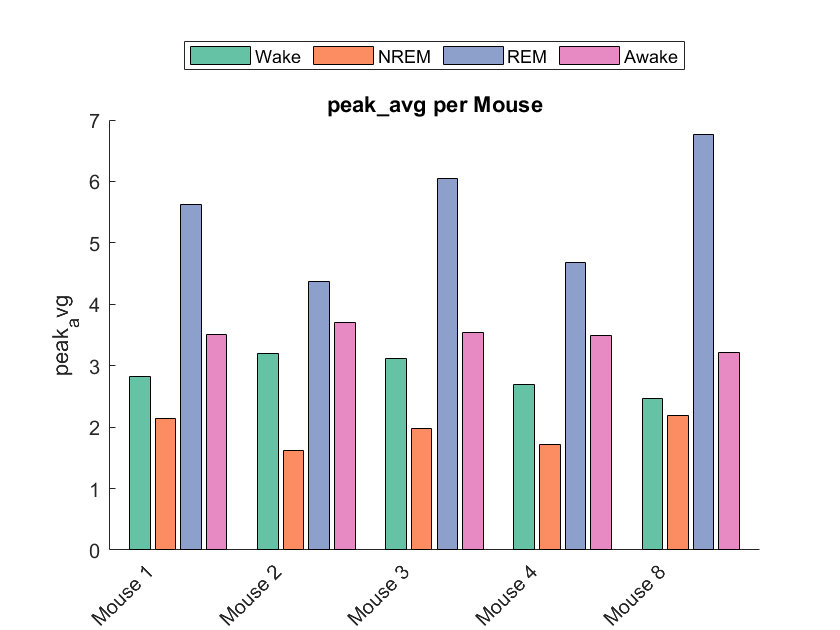

% Define the base names of the metrics
base_metric_names = {'peak_count', 'peak_avg', 'width_avg', 'prom_avg'};

% Extract the unique mice IDs
unique_mice = unique(combined_transients.mouse);

% Define the colormap and score labels
cmap = [102 194 165; 252 141 98; 141 160 203; 231 138 195] / 255;
score_labels = {'Wake', 'NREM', 'REM', 'Awake'};

% Loop through each base metric name
for metric_idx = 1:length(base_metric_names)
    % Initialize a figure for the current metric
    fig = figure;
    hold on;

    % Extract the current base metric name
    base_metric_name = base_metric_names{metric_idx};

    % Loop through each unique mouse ID
    for mouse_idx = 1:length(unique_mice)
        % Extract the current mouse ID
        mouse_id = unique_mice(mouse_idx);

        % Loop through each score
        for score_idx = 1:4
            % Define the full metric name for the current score
            full_metric_name = [base_metric_name, '_score_', num2str(score_idx)];

            % Extract the rows for the current mouse
            mouse_rows = combined_transients.mouse == mouse_id;

            % Calculate the average value for the current mouse and score
            avg_value = nanmean(combined_transients{mouse_rows, full_metric_name});

            % Plot the average value
            bar((mouse_idx-1)*5 + score_idx, avg_value, 'FaceColor', cmap(score_idx, :));
        end
    end

    % Set x-axis ticks and labels
    xticks(1:5:length(unique_mice)*5);
    xticklabels(arrayfun(@(x) sprintf('Mouse %d', x), unique_mice, 'UniformOutput', false));
    xtickangle(45);

    % Set y-axis label
    ylabel(base_metric_name);

    % Set title
    title([base_metric_name, ' per Mouse'], 'Interpreter', 'none');

    % Add legend
    legend(score_labels, 'Location', 'northoutside', 'NumColumns', 4);

    % Save the figure
    saveas(fig, fullfile(parent_folder, [base_metric_name, '_per_mouse.png']));
    close(fig);
end

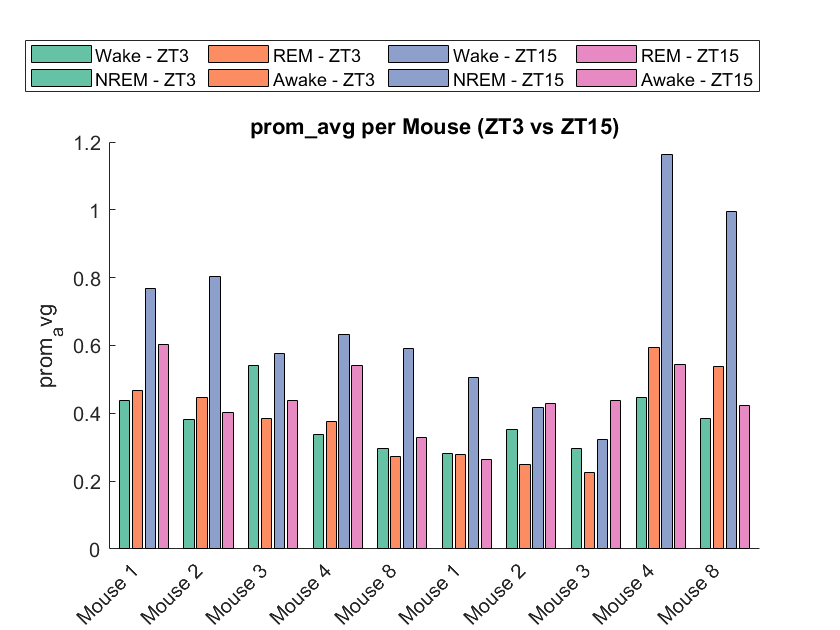

% Define the base names of the metrics
base_metric_names = {'peak_count', 'peak_avg', 'width_avg', 'prom_avg'};

% Extract the unique mice IDs
unique_mice = unique(combined_transients.mouse);

% Define the colormap and score labels
cmap = [102 194 165; 252 141 98; 141 160 203; 231 138 195] / 255;
score_labels = {'Wake', 'NREM', 'REM', 'Awake'};

% Define the ZT values
zt_values = {'3', '15'};

% Loop through each base metric name
for metric_idx = 1:length(base_metric_names)
    % Initialize a figure for the current metric
    fig = figure;
    hold on;

    % Extract the current base metric name
    base_metric_name = base_metric_names{metric_idx};

    % Loop through each unique mouse ID
    for mouse_idx = 1:length(unique_mice)
        % Extract the current mouse ID
        mouse_id = unique_mice(mouse_idx);

        % Loop through each score
        for score_idx = 1:4
            % Define the full metric name for the current score
            full_metric_name = [base_metric_name, '_score_', num2str(score_idx)];

            % Loop through each ZT value
            for zt_idx = 1:length(zt_values)
                % Define the current ZT value
                zt_value = zt_values{zt_idx};

                % Extract the rows for the current mouse and ZT value
                mouse_zt_rows = combined_transients.mouse == mouse_id & ...
                    (strcmp(combined_transients.ZT, zt_value) | (strcmp(zt_value, '15') & strcmp(combined_transients.ZT, '14')));

                % Calculate the average value for the current mouse, ZT value, and score
                avg_value = nanmean(combined_transients{mouse_zt_rows, full_metric_name});

                % Plot the average value
                bar((mouse_idx-1)*10 + (zt_idx-1)*5 + score_idx, avg_value, 'FaceColor', cmap(score_idx, :));
            end
        end
    end

    % Set x-axis ticks and labels
    xticks(1:5:length(unique_mice)*10);
    xticklabels(repmat(arrayfun(@(x) sprintf('Mouse %d', x), unique_mice, 'UniformOutput', false), 1, 2));
    xtickangle(45);

    % Set y-axis label
    ylabel(base_metric_name);

    % Set title
    title([base_metric_name, ' per Mouse (ZT3 vs ZT15)'], 'Interpreter', 'none');

    % Add legend
    legend([strcat(score_labels, ' - ZT3'), strcat(score_labels, ' - ZT15')], 'Location', 'northoutside', 'NumColumns', 4);

    % Save the figure
    saveas(fig, fullfile(parent_folder, [base_metric_name, '_per_mouse_ZT3_vs_ZT15.png']));
    close(fig);
end

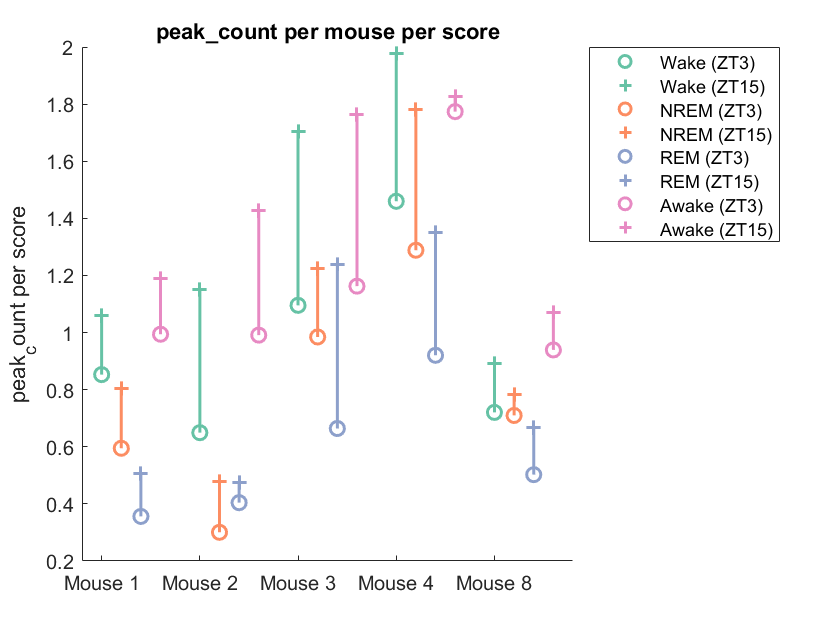

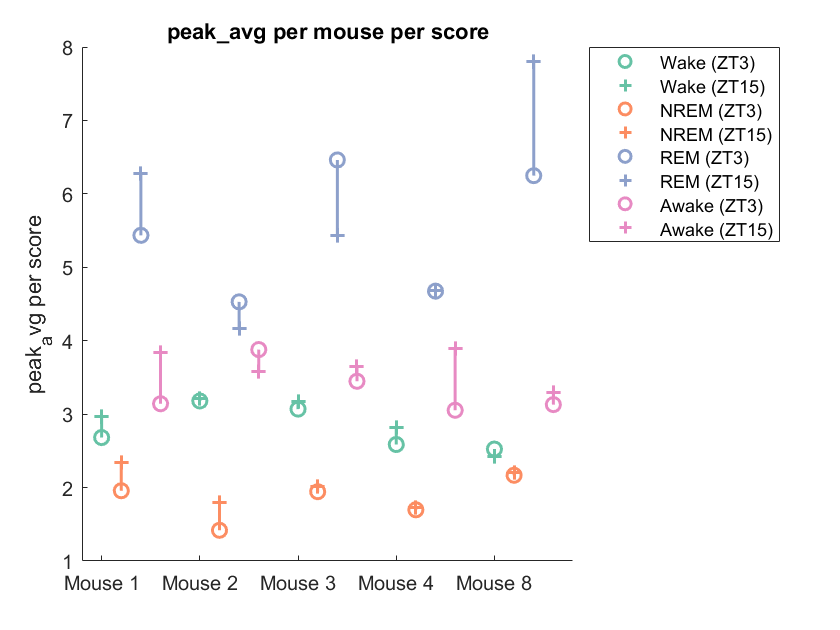

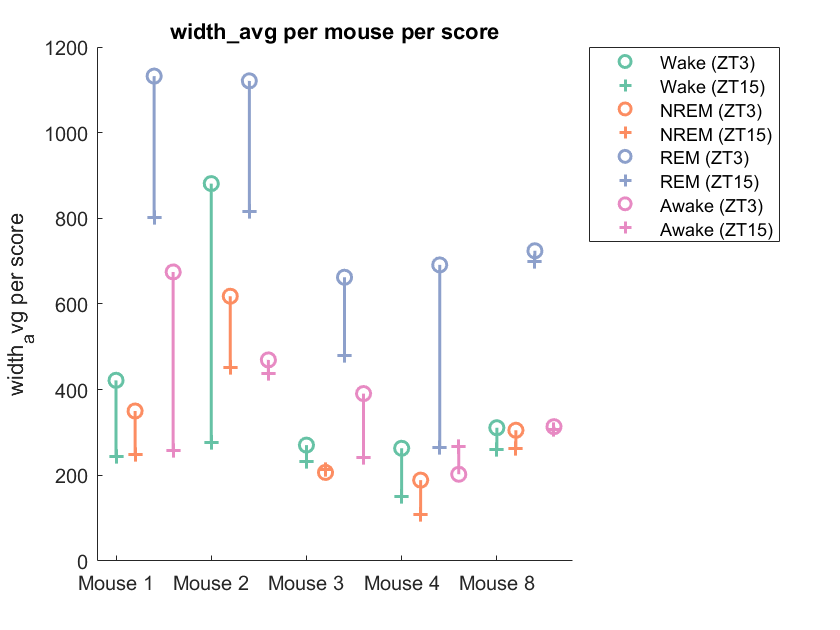

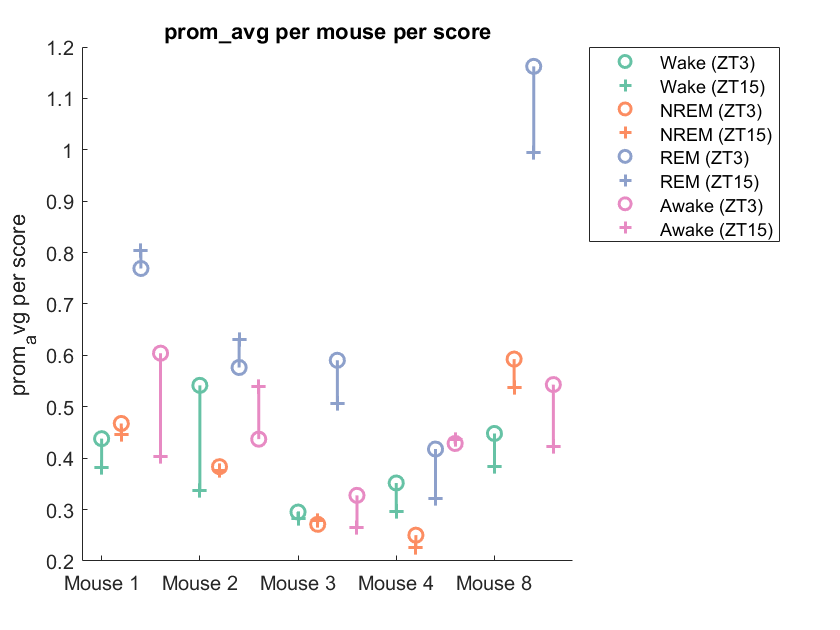

parent_folder = folder_path;
unique_mice = unique(combined_transients.mouse);
unique_zts = {'3', '15'};
metrics = {'peak_count', 'peak_avg', 'width_avg', 'prom_avg'};
score_labels = {'Wake', 'NREM', 'REM', 'Awake'};
markers = 'o+';
cmap = [102 194 165; 252 141 98; 141 160 203; 231 138 195] / 255;

for metric_idx = 1:length(metrics)
    metric = metrics{metric_idx};
    fig = figure;

    % Create dummy plots for the legend
    for score_idx = 1:4
        for zt_idx = 1:length(unique_zts)
            scatter(nan, nan, 50, markers(zt_idx), 'MarkerEdgeColor', cmap(score_idx, :), 'LineWidth', 1.5, 'DisplayName', [score_labels{score_idx} ' (ZT' unique_zts{zt_idx} ')']);
            hold on;
        end
    end

    % Create the legend and set 'AutoUpdate' to 'off'
    legend('Location', 'bestoutside', 'AutoUpdate', 'off');

    % Loop over each mouse
    for mouse_idx = 1:length(unique_mice)
        mouse_id = unique_mice(mouse_idx);

        % Plot ZT3 and ZT15 values for each score
        for score_idx = 1:4
            y = zeros(1,2);

            % Loop over each ZT value
            for zt_idx = 1:length(unique_zts)
                zt_value = unique_zts{zt_idx};

                % Extract the rows for the current mouse and ZT value
                mouse_zt_rows = combined_transients.mouse == mouse_id & ...
                    (strcmp(combined_transients.ZT, zt_value) | (strcmp(zt_value, '15') & strcmp(combined_transients.ZT, '14')));

                % Get the metric value for the current mouse, score and ZT value
                y(zt_idx) = nanmean(combined_transients{mouse_zt_rows, [metric '_score_' num2str(score_idx)]});
            end

            % Adjust x for each score type to avoid overlap
            x = (mouse_idx-1)*5 + score_idx;

            % Plot ZT3 and ZT15 values
            for zt_idx = 1:length(unique_zts)
                scatter(x, y(zt_idx), 50, markers(zt_idx), 'MarkerEdgeColor', cmap(score_idx, :), 'LineWidth', 1.5);
                hold on;
            end

            % Plot a line connecting the ZT3 and ZT15 values
            plot(x*ones(size(y)), y, 'Color', cmap(score_idx, :), 'LineWidth', 1.5);
        end
    end

    % Adjust x-axis
    xticks(1:5:length(unique_mice)*5);
    xticklabels(arrayfun(@(x) sprintf('Mouse %d', x), unique_mice, 'UniformOutput', false));

    % Set y-axis label
    ylabel([metric ' per score']);
    % Set title
    title([metric ' per mouse per score'], 'Interpreter', 'none');

    % Save the figure
    saveas(fig, fullfile(parent_folder, [metric '_per_mouse_per_score_ZT.png']));
    close(fig);
end


% Define the metrics and scores
metrics = {'peak_count', 'peak_avg', 'width_avg', 'prom_avg'};
score_labels = {'wake', 'NREM', 'REM', 'Awake'};

% Loop through each metric
for i = 1:length(metrics)
    metric = metrics{i};

    % Select the columns corresponding to the current metric
    metric_cols = contains(combined_transients.Properties.VariableNames, [metric '_']);
    % Convert the logical index to a numeric index
    metric_cols_idx = find(metric_cols);

    % Combine the numeric index with the positional index
    metric_table = combined_transients(:, [metric_cols_idx, (width(combined_transients)-2):width(combined_transients)]);


    % Replace the score names in the column names
    metric_table.Properties.VariableNames = strrep(metric_table.Properties.VariableNames, 'score_', '');
    for j = 1:4
        metric_table.Properties.VariableNames = strrep(metric_table.Properties.VariableNames, num2str(j), score_labels{j});
    end

    % Save the table to a CSV file
    writetable(metric_table, fullfile(parent_folder,[metric '_transients.csv']));
end


[p,s,mu] = polyfit((1:numel(noisyECG_withTrend))',noisyECG_withTrend,6);
f_y = polyval(p,(1:numel(noisyECG_withTrend))',[],mu);


